**Question 3 **

DATA_Trip_File.csv file, 

only work with data that relates to trips made by public transport

consider  the average TRPMILES that a person made on their survey day as the random variable of  interest.

**Load Data**

clear
close all;
% DATA_Trip_File = xlsread("DATA_Trip_File.csv");
load('DATA_Trip_File.mat')


**Extract Required Data**

% Extract the data which related to public transport
Position_3 = find(DATA_Trip_File(:,11)==3);% MODE=3
Position_4 = find(DATA_Trip_File(:,11)==4);% MODE=4
Position_6 = find(DATA_Trip_File(:,11)==6);% MODE=6
Position = [Position_3;Position_4;Position_6];

DATA_Trip_File_Public = DATA_Trip_File(Position,:);

Same_HouseID = diff(DATA_Trip_File_Public(:,1)); % Check if adjacent House is the same House
Same_PersonID = diff(DATA_Trip_File_Public(:,2)); % Check if adjacent Person shares the same Person ID
% Check if adjacent Person is the same Person
% Same_Person = 1 --> the same person; Same_Person = 0 --> not the same person; 
Same_Person = (Same_HouseID == 0)&(Same_PersonID == 0); 

Same_Person_Completion = [0;Same_Person;0]; % Add 0 before and after Same_Person and then use diff,


%Copy the original data
DATA_Trip_File_Public_Copy = DATA_Trip_File_Public; 

k = diff(Same_Person_Completion);       
% add 1 is for the right index after diff()
% ind denotes the 
ind = find(k==1)+1; 
% the position differences between-1 and 1 apears is the number of times of 1
num = find(k==-1)-ind+1;

% clear Average_TripMiles

for n = 1:length(ind)
        Person_Num = [ind(n)-1:1:ind(n)+num(n)-1]; % repeatly persons'index（no.n group）,react original data's rows'sequence numbers
        Average_Age(n) = mean(DATA_Trip_File_Public(Person_Num,3));
        Average_TripMiles(n) = mean(DATA_Trip_File_Public(Person_Num,8)) ;
        % make data from DATA_Trip_File_Public_Copy which already 'averaged'equal to zero, delete after the loop 
        DATA_Trip_File_Public_Copy(Person_Num,:) = zeros;
end

% find the rows from DATA_Trip_File_Public_Copy which were made in zero
Zero_Row_Num = find(DATA_Trip_File_Public_Copy(:,1)==0);
% delete them, finally i got good samples
DATA_Trip_File_Public_Copy(Zero_Row_Num,:) = [];

% completely data
Age_Needed = [Average_Age,DATA_Trip_File_Public_Copy(:,3)'];
Average_TripMiles_Needed = [Average_TripMiles,DATA_Trip_File_Public_Copy(:,8)'];

Next, suppose that the collection of average TRPMILES from all survey participants is IID

Let Sn denote the sum of all of these average  TRPMILES measurements, 

Mn denote the sample mean of the average TRPMILES  measurements, 

where n is the total number of these measurements (i.e., n is the sample  size).

**Question 3-a**

a) Compute Mn.

Sn(1) = Average_TripMiles_Needed(1)% Initialized the sum of n samples

Sn = 10

Mn(1) = Sn(1)/1

Mn = 10

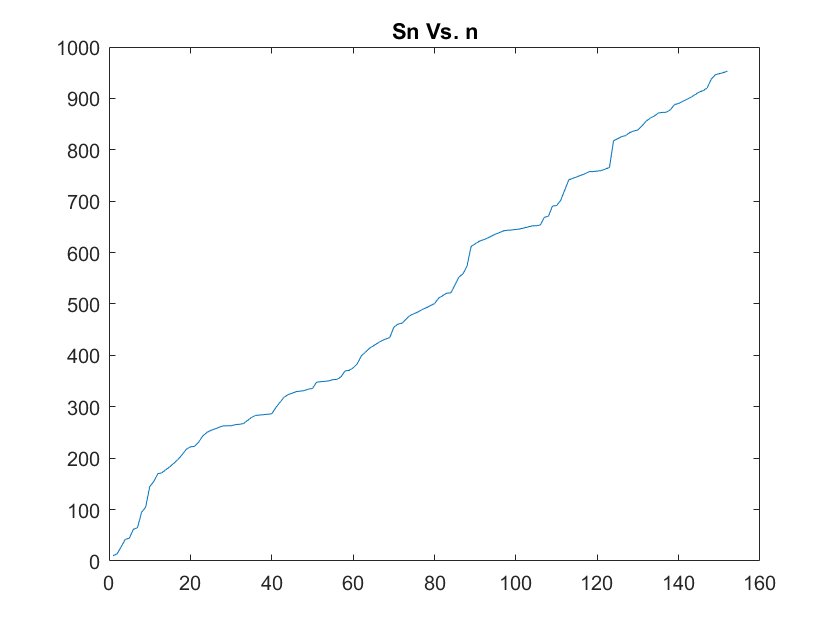


for n=2:length(Average_TripMiles_Needed)
    Sn(n) = Sn(n-1) + Average_TripMiles_Needed(n);
    Mn(n) = Sn(n)/n;
end

close all;

n = length(Average_TripMiles_Needed);

figure(2)
plot([1:n],Sn)
title('Sn Vs. n')

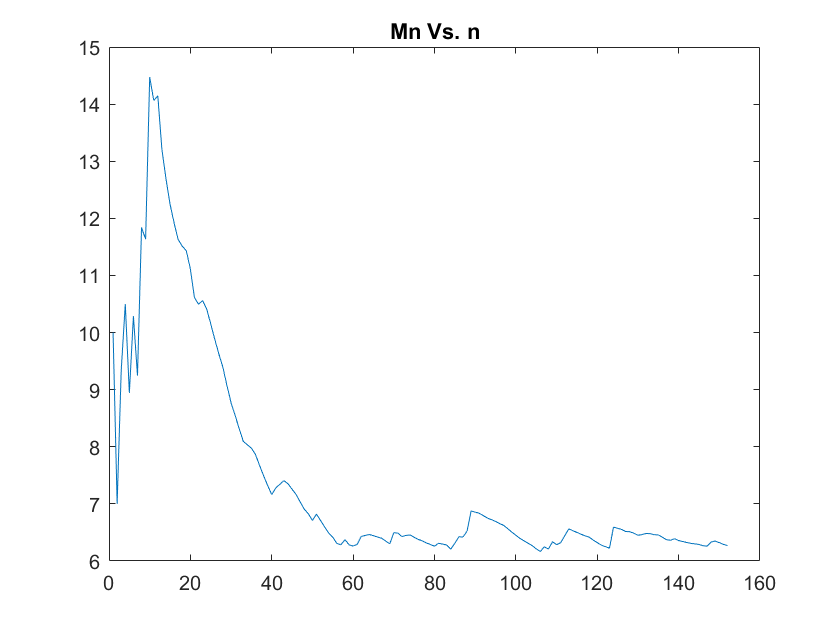


figure(3)
plot([1:n],Mn)
title('Mn Vs. n')

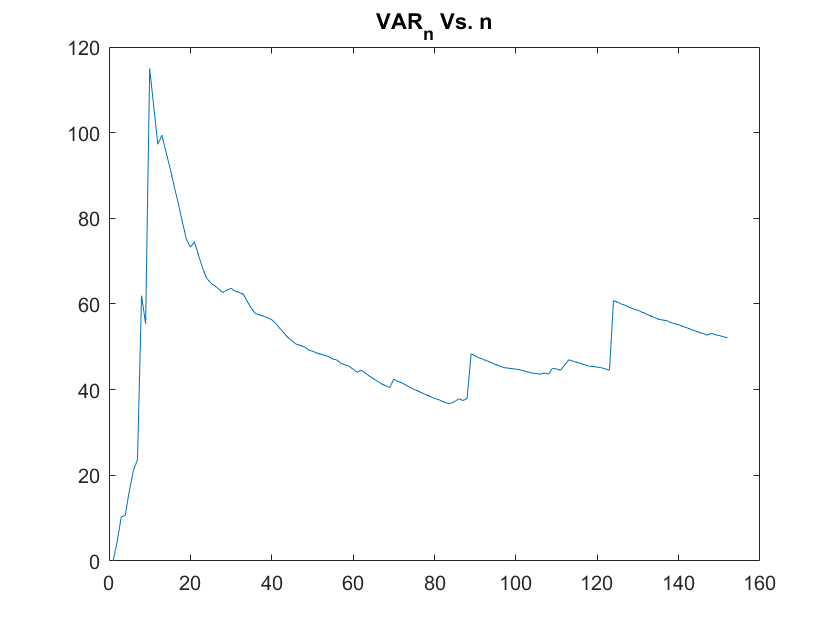

Sum_Sample_Square = 0;

for n = 1:length(Average_TripMiles_Needed)
    Sum_Sample_Square = Sum_Sample_Square + (Average_TripMiles_Needed(n)-Mn(n))^2;
    Variance_1(n) = Sum_Sample_Square/n;
end

close all;
figure(4)
n = length(Average_TripMiles_Needed);
plot(1:n,Variance_1)
title('VAR_n Vs. n')


VAR_1_End = Variance_1(end)

VAR_1_End = 52.1138

Variance_2 = var(Average_TripMiles_Needed)

Variance_2 = 54.3106

Target_Deviation = sqrt(Variance_2)/10

Target_Deviation = 0.7370

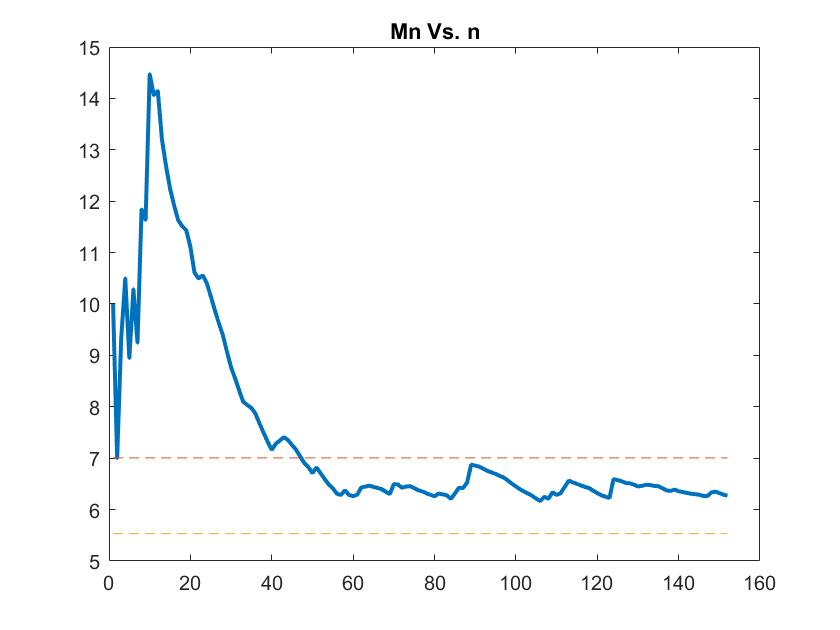


figure(5)

plot([1:n],Mn,'linewidth',2)
hold on 
plot([1:n],ones(1,n)*(Mn(end)+Target_Deviation),'--')
plot([1:n],ones(1,n)*(Mn(end)-Target_Deviation),'--')
title('Mn Vs. n')